clear;

% ddu/dyy + ddu/dxx = x^2 + y^2-
% [0,1] x [0,1]
f = @(x,y) x.^2 + y.^2;

N = 20;
h = 1/N;
x = 0:h:1;
y = 0:h:1;
[X,Y] = meshgrid(x,y);

w = zeros(N+1,N+1);

for i = 1:N+1
    w(i,1) = 0;
    w(i,N+1) = 0;
end

for j = 1:N+1
    w(1,j) = 0;
    w(N+1,j) = 0;
end

n = N-1;
I = eye(n);
c = [-2 1 zeros(1,n-2)];
D = toeplitz(c);
D = kron(D,I) + kron(I,D);
% spy(D)

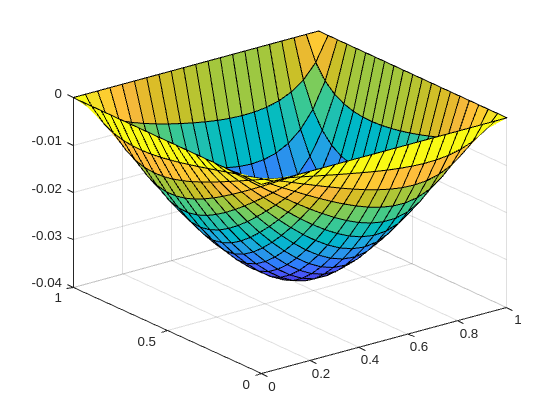

F = h^2*f(Y(1:n,1:n),X(1:n,1:n));
F = F(:);

U = D \ F;
U = reshape(U,n,n);
w(2:N,2:N) = U;
surf(X,Y,w)